A = [infsup(0, 2), infsup(1, 3); 1, -infsup(2, 4); infsup(1, 3), 0];
b = [infsup(3, 7); 0; infsup(5, 7)];
Tol = @(A, b, x) min(rad(b) - mag(mid(b) - A * x));

[origtolmax,origargmax,envs,ccode] = tolsolvty(inf(A), sup(A), inf(b), sup(b));

 
 Допусковое множество решений интервальной линейной системы пусто 
 


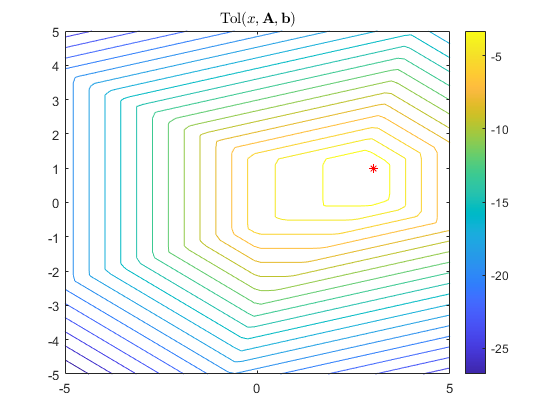

n = 60;
levels = n / 3;
x = linspace(-5, 5, n);
y = linspace(-5, 5, n);
[xx, yy] = meshgrid(x, y);
zz = zeros([size(xx, 1), size(xx, 2)]);
for i=1:size(xx, 1)
    for j=1:size(yy,1)
        zz(i, j) = Tol(A, b, [xx(i, j); yy(i, j)]);
    end
end
figure
contour(xx, yy, zz, levels)
hold on
plot(origargmax(1), origargmax(2), 'r*')
hold on 
colorbar
title('Tol($x, \mathbf{A}, \mathbf{b}$)','interpreter','latex')

e = [infsup(-1, 1); infsup(-1, 1); infsup(-1, 1)];
C = 1.5 * abs(origtolmax);
b1 = b + C * e;
[btolmax,bargmax,envs,ccode] = tolsolvty(inf(A), sup(A), inf(b1), sup(b1));

 
 Допусковое множество решений интервальной линейной системы непусто 
 


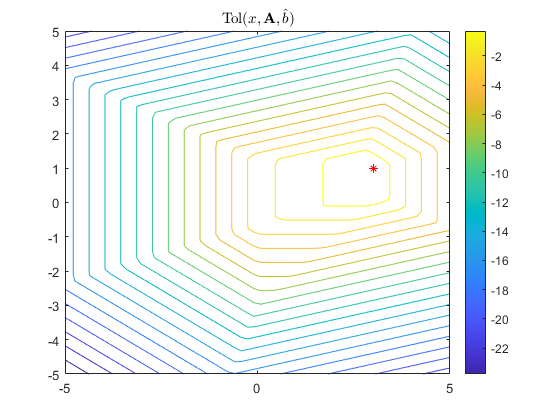

zz = zeros([size(xx, 1), size(xx, 2)]);
for i=1:size(xx, 1)
    for j=1:size(yy,1)
        zz(i, j) = Tol(A, b1, [xx(i, j); yy(i, j)]);
    end
end
figure
contour(xx, yy, zz, levels)
hold on
plot(bargmax(1), bargmax(2), 'r*')
hold on 
colorbar
title('Tol($x, \mathbf{A}, \hat{b}$)','interpreter','latex')

[V,P1,P2,P3,P4] = EqnTolR2(inf(A), sup(A), inf(b1), sup(b1));

Число ориентиров = 6



iveVal = ive(A, b1);

 
 Допусковое множество решений интервальной линейной системы непусто 
 


rveVal = rve(A, b1);

 
 Допусковое множество решений интервальной линейной системы непусто 
 


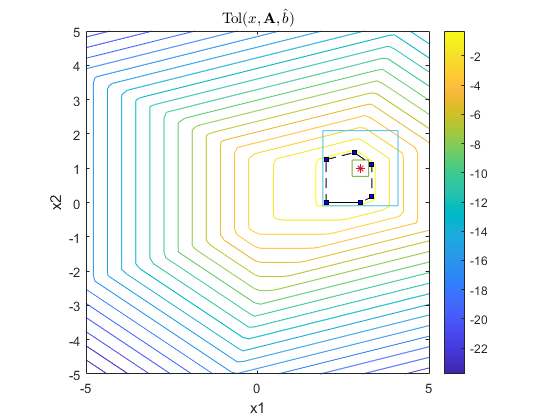

iveInt = [midrad(bargmax(1), iveVal);midrad(bargmax(2), iveVal)];
rveInt = [midrad(bargmax(1), rveVal);midrad(bargmax(2), rveVal)];
plotintval([iveInt, rveInt], 'n')

AETol = @(A, E, b, x) min(rad(b) - mag(mid(b) - A * x) + abs(E * x));
E = 1 * [origargmax(1) * 0.25 origargmax(2);0 origargmax(2);origargmax(1) * 0.25 0];
%E = infsup([-1 -1; -1 -1; -1 -1], [1 1; 1 1; 1 1]);
A1 = infsup(inf(A) + E, sup(A) - E);
zz = zeros([size(xx, 1), size(xx, 2)]);
for i=1:size(xx, 1)
    for j=1:size(yy,1)
        zz(i, j) = Tol(A1, b, [xx(i, j); yy(i, j)]);
    end
end
[aetolmax,aeargmax,envs,ccode] = tolsolvty(inf(A1), sup(A1), inf(b), sup(b));

 
 Допусковое множество решений интервальной линейной системы непусто 
 


figure
contour(xx, yy, zz, levels)
hold on
plot(aeargmax(1), aeargmax(2), 'r*')
hold on 
colorbar
title('Tol($x, \hat{A}, \mathbf{b}$)','interpreter','latex')
[V,P1,P2,P3,P4] = EqnTolR2(inf(A1), sup(A1), inf(b), sup(b));

Число ориентиров = 2



iveVal = ive(A1, b);

 
 Допусковое множество решений интервальной линейной системы непусто 
 


rveVal = rve(A1, b);

 
 Допусковое множество решений интервальной линейной системы непусто 
 


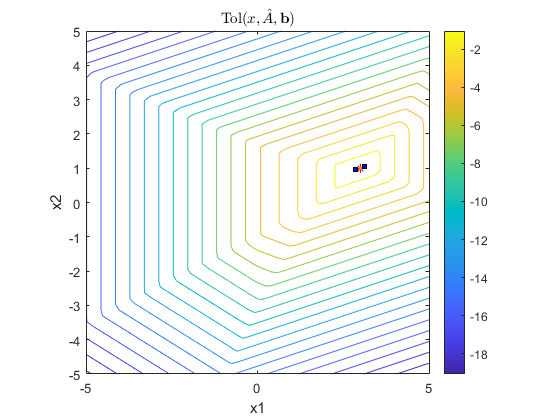

iveInt = [midrad(aeargmax(1), iveVal);midrad(aeargmax(2), iveVal)];
rveInt = [midrad(aeargmax(1), rveVal);midrad(aeargmax(2), rveVal)];
plotintval([iveInt, rveInt], 'n')

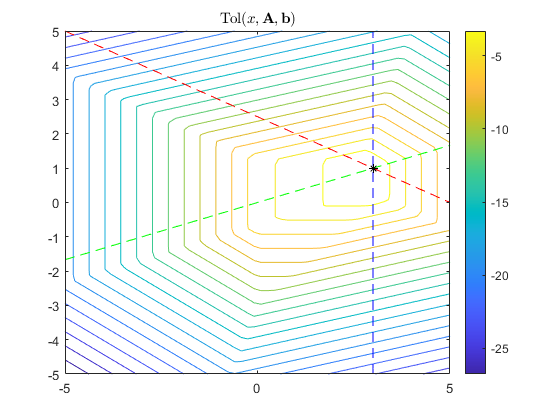

AENTol = @(A, E, b, x) min(rad(b) - mag(mid(b) - A * x) + abs(E * x));
line1 = @(x) (mid(b(1)) - mid(A(1, 1)) * x) / mid(A(1, 2));
line2 = @(x) (mid(b(2)) - mid(A(2, 1)) * x) / mid(A(2, 2));
line3 = @(y) mid(b(3)) / mid(A(3, 1)) * ones(size(y));
zz = zeros([size(xx, 1), size(xx, 2)]);
for i=1:size(xx, 1)
    for j=1:size(yy,1)
        zz(i, j) = Tol(A, b, [xx(i, j); yy(i, j)]);
    end
end
figure
contour(xx, yy, zz, levels)
hold on
plot(x, line1(x), 'r--')
hold on 
plot(x, line2(x), 'g--')
hold on 
plot(line3(y), y, 'b--')
hold on
plot(origargmax(1), origargmax(2), 'k*')
hold on 
colorbar
title('Tol($x, \mathbf{A}, \mathbf{b}$)','interpreter','latex')

N = [1 0 0;0 1 0;0 0 1];
E = 0.5 * N * [1 1;0 1;1 0];
%E = infsup([-1 -1; -1 -1; -1 -1], [1 1; 1 1; 1 1]);
A2 = infsup(inf(A) + E, sup(A) - E);
A2

intval A2 = 
[    0.5000,    1.5000] [    1.5000,    2.5000] 
[    1.0000,    1.0000] [   -3.5000,   -2.5000] 
[    1.5000,    2.5000] [    0.0000,    0.0000] 


for i=1:size(xx, 1)
    for j=1:size(yy,1)
        zz(i, j) = Tol(A2, b, [xx(i, j); yy(i, j)]);
    end
end
[~,aeargmaxEYE,envs,ccode] = tolsolvty(inf(A2), sup(A2), inf(b), sup(b));

 
 Допусковое множество решений интервальной линейной системы пусто 
 


aeargmaxEYE

aeargmaxEYE =             3
            1


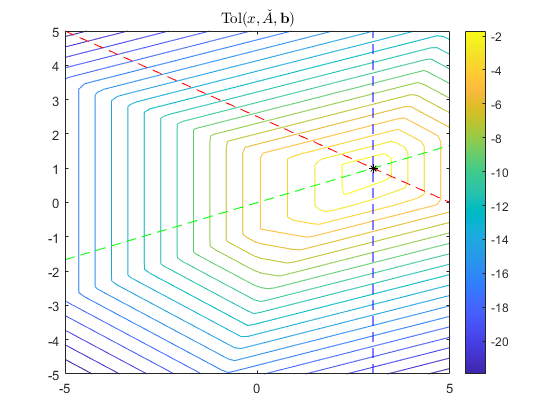

figure
contour(xx, yy, zz, levels)
hold on
plot(x, line1(x), 'r--')
hold on 
plot(x, line2(x), 'g--')
hold on 
plot(line3(y), y, 'b--')
hold on
plot(aeargmaxEYE(1), aeargmaxEYE(2), 'k*')
hold on 
colorbar
title('Tol($x, \check{A}, \mathbf{b}$)','interpreter','latex')

mesh(xx, yy, zz)

Множество решений пусто (нет граничных интервалов)


N = [1 0 0;0 0 0;0 0 0];
E = 1 * N * [1 1;0 1;1 0];
%E = infsup([-1 -1; -1 -1; -1 -1], [1 1; 1 1; 1 1]);
A2 = infsup(inf(A) + E, sup(A) - E);
A2

intval A2 = 
[    1.0000,    1.0000] [    2.0000,    2.0000] 
[    1.0000,    1.0000] [   -4.0000,   -2.0000] 
[    1.0000,    3.0000] [    0.0000,    0.0000] 


zz = zeros([size(xx, 1), size(xx, 2)]);
for i=1:size(xx, 1)
    for j=1:size(yy,1)
        zz(i, j) = Tol(A2, b, [xx(i, j); yy(i, j)]);
    end
end
[~,aeargmax1,envs,ccode] = tolsolvty(inf(A2), sup(A2), inf(b), sup(b));

 
 Допусковое множество решений интервальной линейной системы пусто 
 


aeargmax1

aeargmax1 =             3
            1


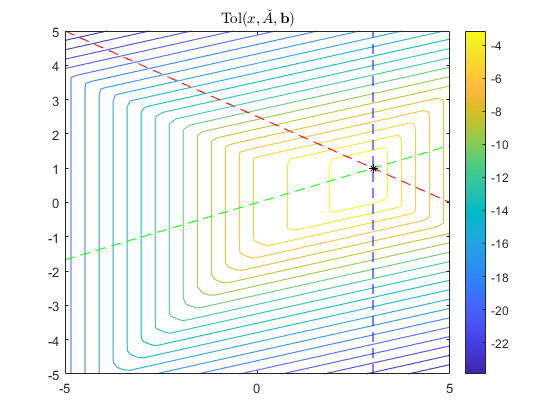

figure
contour(xx, yy, zz, levels)
hold on
plot(x, line1(x), 'r--')
hold on 
plot(x, line2(x), 'g--')
hold on 
plot(line3(y), y, 'b--')
hold on
plot(aeargmax1(1), aeargmax1(2), 'k*')
hold on 
colorbar
title('Tol($x, \check{A}, \mathbf{b}$)','interpreter','latex')

N = [0 0 0;0 1 0;0 0 0];
E = 1 * N * [1 1;0 1;1 0];
%E = infsup([-1 -1; -1 -1; -1 -1], [1 1; 1 1; 1 1]);
A2 = infsup(inf(A) + E, sup(A) - E);
A2

intval A2 = 
[    0.0000,    2.0000] [    1.0000,    3.0000] 
[    1.0000,    1.0000] [   -3.0000,   -3.0000] 
[    1.0000,    3.0000] [    0.0000,    0.0000] 


zz = zeros([size(xx, 1), size(xx, 2)]);
for i=1:size(xx, 1)
    for j=1:size(yy,1)
        zz(i, j) = Tol(A2, b, [xx(i, j); yy(i, j)]);
    end
end
[~,aeargmax2,envs,ccode] = tolsolvty(inf(A2), sup(A2), inf(b), sup(b));

 
 Допусковое множество решений интервальной линейной системы пусто 
 


aeargmax2

aeargmax2 =             3
            1


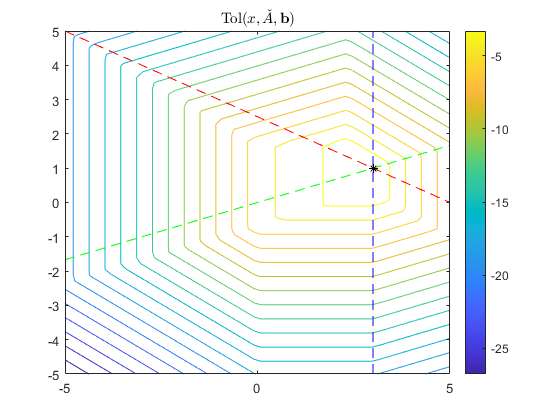

figure
contour(xx, yy, zz, levels)
hold on
plot(x, line1(x), 'r--')
hold on 
plot(x, line2(x), 'g--')
hold on 
plot(line3(y), y, 'b--')
hold on
plot(aeargmax2(1), aeargmax2(2), 'k*')
hold on 
colorbar
title('Tol($x, \check{A}, \mathbf{b}$)','interpreter','latex')

N = [0 0 0;0 0 0;0 0 1];
E = 1 * N * [1 1;0 1;1 0];
%E = infsup([-1 -1; -1 -1; -1 -1], [1 1; 1 1; 1 1]);
A2 = infsup(inf(A) + E, sup(A) - E);
A2

intval A2 = 
[    0.0000,    2.0000] [    1.0000,    3.0000] 
[    1.0000,    1.0000] [   -4.0000,   -2.0000] 
[    2.0000,    2.0000] [    0.0000,    0.0000] 


zz = zeros([size(xx, 1), size(xx, 2)]);
for i=1:size(xx, 1)
    for j=1:size(yy,1)
        zz(i, j) = Tol(A2, b, [xx(i, j); yy(i, j)]);
    end
end
[~,aeargmax3,envs,ccode] = tolsolvty(inf(A2), sup(A2), inf(b), sup(b));

 
 Допусковое множество решений интервальной линейной системы пусто 
 


aeargmax3

aeargmax3 =        2.7143
       1.1429


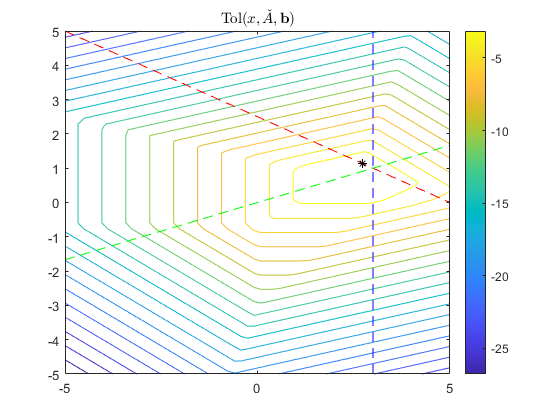

figure
contour(xx, yy, zz, levels)
hold on
plot(x, line1(x), 'r--')
hold on 
plot(x, line2(x), 'g--')
hold on 
plot(line3(y), y, 'b--')
hold on
plot(aeargmax3(1), aeargmax3(2), 'k*')
hold on 
colorbar
title('Tol($x, \check{A}, \mathbf{b}$)','interpreter','latex')